cwd = fileparts(matlab.desktop.editor.getActiveFilename);%import functions from src
src_path = fullfile(cwd, "src");

src_path = "/home/ben/ibots/iBOTS-Tools/workshops/matlab-workshop-1/plan/day1/src"

userpath(src_path)

## Experimental Data

In this workshop we will be analysing data of Nicholas Steinmetz and colleagues from their 2019 Nature publication. The code below will download the paper - click on the grey cell and press Ctrl + Enter.

download_from_sciebo("https://uni-bonn.sciebo.de/s/xUrHMXlJQegOtAN", 'steinmetz2019.pdf')

In the experiment, trained mice performed a discrimination task with their choices reported by turning a steering wheel. 

The mice were presented with two stimuli on a screen, one on the left and one on the right. Their task was to turn a steering wheel such that the brighter stimulus moves into the center. If the mice perform the task correctly, they are rewarded with a drink of water. 

During the experiment, neural activity was recorded via NeuroPixels probes, which are dense arrays of electrodes that can measure the activity of several hundred neurons at once. 

The dataset is a rich source with behavioural and neural data that is just waiting to be explored with Matlab!

 An excellent description of the experiment is given in this [10 minute video](https://www.youtube.com/watch?v=WXn4-FpVaOo) by the study's lead author, Nicholas Steinmetz.

# Introduction to Matlab Live Scripts

Have you ever seen a wall of code like so that doesn't make any sense to you? 

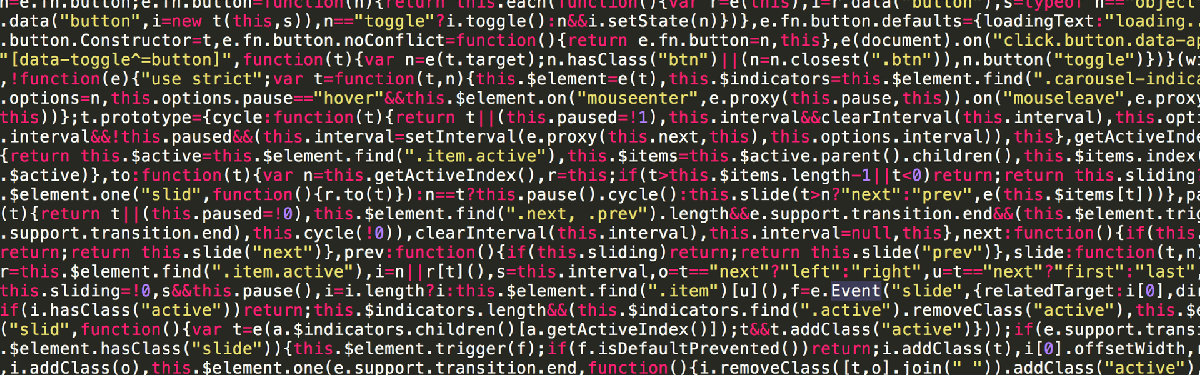

**A Matlab live script is the perfect antitode! **

With a live script, we can write and run Matlab code with added bonuses: 

- Annotate code with formatted text (eg. bullet points, section headers, hyperlinks, images and more)

- split code up into sections that can be run independantly 

In this session we will go through the basic features of a live script and how to work with Matlab.

## Coding Made Easy with Tasks

First, let's download a data file from sciebo for the exercises in this live script. The data is hosted on sciebo at the url: [https://uni-bonn.sciebo.de/s/9FxelLhARmHpw85](https://uni-bonn.sciebo.de/s/9FxelLhARmHpw85)

Fill in the blank below to download the datafile

url= ___
download_from_sciebo(url, 'data/steinmetz_winter2017.csv')

Done!

Matlab makes complex tasks like plotting the work of a few clicks with tasks

Use the Task below to import the file `steinmetz_winter2017.csv` from the directory `data`

The Create Plot task allows us to make any plot we want - try it out with the data imported from the previous cell

Tasks produce Matlab code, in the "Show code" section at the bottom of the task. This code can be further edited to suit your purpose. 

Many other tasks are available. You can even create your own custom-made tasks with the "Create a Task" task! 

The Task menu is in the `CODE` section in the` LIVE EDITOR` tab in the top menu.

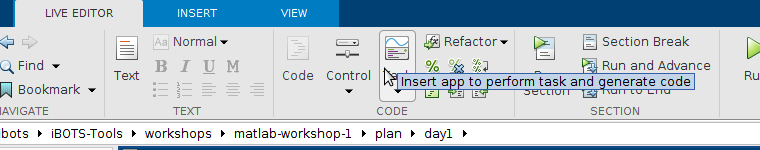

Explore the "Compute by Group" task to see what is does.

## Your First Live Script 

### Writing Code and Text

To make a new Live Script, select Live Script from the New menu in the upper left corner.

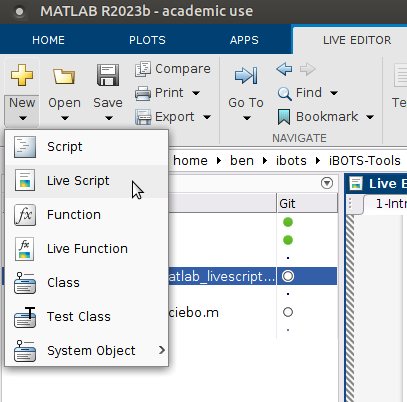

In the new live script, you can immediately start writing Matlab code.

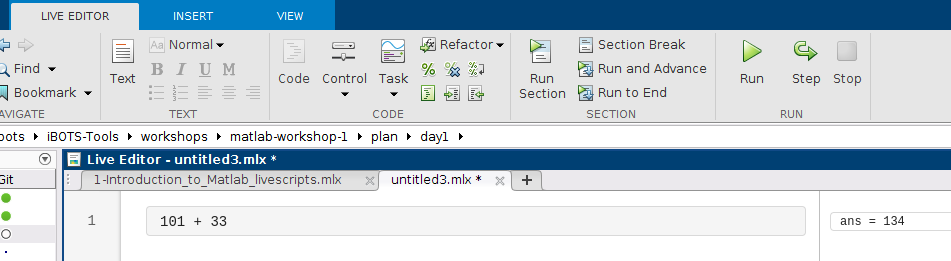

Run the whole live script by pressing the green "Run" arrow on the top right and the code's output is displayed on the right.

To switch between writing code and text, use the "Text" and "Code" buttons on the top menu

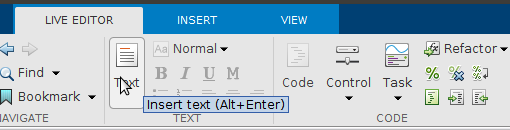

### Sections

A live script can be split into sections that run independantly. To make a new section, press the "Section Break" button on the top menu.

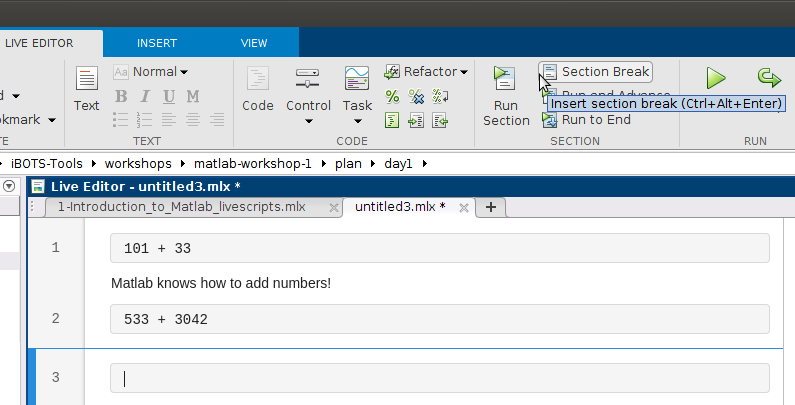

Sections are divided by pale blue lines and the section you are currently working on is highlighted by a blue box.

To execute the code in a section, press the "Run Section" button (or use Ctrl + Enter). Note that this is different from the "Run" button, which runs all sections of the live script.

Feel free to experiment with sections, writing and formatting text and writing code!

## Coding in Matlab

Matlab was first developed in the late 1970s, making it one of the oldest programming languages that is still widely used today. It was initially for carrying out matrix calculations, and these roots are still visible today. 

For example, let's define a list of numbers

my_array = [0,2,4,7,9]

my_array =      0     2     4     7     9


This is shown in the output on the right as a "1x5" matrix. 

What happens when we do a transpose? This is done with an apostrophe '

Use the cell below to transpose my_array

What do you notice?

Matlab is a communicative programming language- the output of every line of code is displayed in the panel on the right. To silence this output, simply end the line with a semi-colon ;

Define a new variable `my_second_array` that contains 5 elements. End your line of code with a semi-colon.

### Multiplication 

Let's multiply my_array and my_second_array together and see what happens.

Do that in the cell below

Oh no! It doesn't work because Matlab explicitly assumes that we want to do matrix multiplication. Matrix multipication has its own set of rules, and we have to follow them.

Instead, do the multiplication with one of the matrices transposed. 

ans =      0     2     4     7     9
     0     2     4     7     9
     0     2     4     7     9
     0     4     8    14    18
     0     4     8    14    18


Now do the multiplication with the other matrix transposed

ans = 38

What do you notice? Matrix multiplication is quite strange indeed...

In data analysis however, when you want to multiply two arrays, you probably want to multiply them element-wise. We can do this with the `.*` operator.

In the cell below, multiply `my_array` and `my_second_array` together element-wise

ans =      0     2     4    14    18


### Division

In many programming languages, division is done with the `/` operator

Use the `/` operator on  `my_array `and  `my_second_array`

ans = 3.4545

Did you expect that? 

In Matlab, the `/` operator does not perform a division. It infact solves a system of linear matrix equations.

To find out more, highlight` /` in the cell above, right click and choose "Help on "/" " . 

In the cell below, use the `./` operator on `my_array `and  `my_second_array `to find out what it does

ans =          0    2.0000    4.0000    3.5000    4.5000


**The lesson here is that Matlab understands and expects everything to be in terms of matrices - this can either be a blessing or a curse!**

Comments in Matlab are made with the % sign. Try it out in the cell below

### Workspace variables

Matlab makes it easy to keep track of our variables with the Workspace. Variable names and values are listed in the rightmost pane.

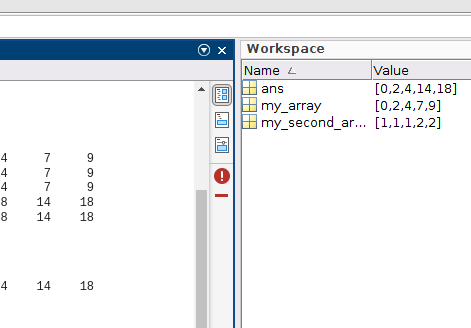

We can see that values of` my_array `and `my_second_array. `

We also see` ans `(short for answer)` - `this is the value of the last output. 

Let's run the section below and see what happens to `ans `

"the answer has changed!"

ans = "the answer has changed!"

When a variable in the Workspace is double clicked, it is displayed in its entirety in a Excel-like spreadsheet. 

All variables can be deleted from the workspace by right clicking on the pane and choosing "clear workspace"

A handy way of storing large amounts of data is in a table. Let's explore some features of a table

Load the data downloaded earlier into Matlab as a table using the `readtable` function. Name the result `data`

data = 7906×15 table
    trial    active_trials    contrast_left    contrast_right    stim_onset    gocue_time    response_type    response_time    feedback_time    feedback_type    reaction_time    reaction_type       mouse       session_date    session_id
    _____    _____________    _____________    ______________    __________    __________    _____________    _____________    _____________    _____________    _____________    _____________    ___________    ____________    __________

Now `data` appears as a 7906x15 table in the Workspace. 

By clicking on it, we can view the tabular data and even sort by certain columns by clicking on the column names. 